% Параметры задачи
L = 1.0;
N = 101;
h = L / (N - 1);

q = 10;
p = 1;
k = 3/2;


A = sparse(N^2, N^2);
F = zeros(N^2, 1);

% Составление матрицы СЛАУ 

for i = 1:N-1
    for j = 1:N-1

        P00 = [(j - 1) * h, (i - 1) * h];
        P10 = [j * h, (i - 1) * h];
        P01 = [(j - 1) * h, i * h];
        P11 = [j * h, i * h];

        n00 = idx(j, i, N);
        n10 = idx(j + 1, i, N);
        n01 = idx(j, i + 1, N);
        n11 = idx(j + 1, i + 1, N);
        
        xc = P00(1); yc = P00(2);
        % Для скалярных x, y
        if (xc < L/2) && (yc < L/2)
            kappa = diag([1 / k, k]);
        elseif (xc >= L/2) && (yc < L/2)
            kappa = diag([k,1/k]);
        elseif (xc < L/2) && (yc >= L/2)
            kappa = diag([k,k]);
        else
            kappa = diag([1/k,1/k]);
        end

        [K1, M1] = local_matrices(P00, P10, P01, kappa, q);
        nodes1 = [n00, n10, n01];
        A(nodes1, nodes1) = A(nodes1, nodes1) + (K1 + M1);

        [K2, M2] = local_matrices(P11, P01, P10, kappa, q);
        nodes2 = [n11, n01, n10];
        A(nodes2, nodes2) = A(nodes2, nodes2) + (K2 + M2);
       
    end
end
nnz(A)

ans = 70601

sum(A(:))

ans =    (1,1)       9.9997



% После сборки A и F, ДО Дирихле
zero_rows = find(all(A==0, 2));
zero_diag = find(diag(A)==0);
fprintf('Число нулевых строк: %d\n', numel(zero_rows));

Число нулевых строк: 0


fprintf('Номера нулевых строк: '); disp(zero_rows');

Номера нулевых строк: 

fprintf('Число нулевых диагоналей: %d\n', numel(zero_diag));

Число нулевых диагоналей: 0


fprintf('Номера: '); disp(zero_diag');

Номера: 


for k = zero_rows'
    [j, i] = ind2sub([N, N], k);   % если idx = (i-1)*N + j
    fprintf('Узел %d: j=%d, i=%d, coord=(%g, %g)\n', k, j, i, (j-1)*h, (i-1)*h);
end

% Граничные условия

% Нейман
for i = 1:N-1
    n1 =  idx(1, i, N);
    n2 =  idx(1, i + 1, N);
    F(n1) = F(n1) + p*(h / 2);
    F(n2) = F(n2) + p*(h / 2);

    n1 =  idx(N, i, N);
    n2 =  idx(N, i + 1, N);
    F(n1) = F(n1) + p*(h / 2);
    F(n2) = F(n2) + p*(h / 2);
end

% Дирихле
dirichle_nodes = [];
for j = 1:N
    dirichle_nodes(end+1) = idx(j, 1, N);
    dirichle_nodes(end+1) = idx(j, N, N);
end
dirichle_nodes = unique(dirichle_nodes)

dirichle_nodes =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50



for k = dirichle_nodes
    A(k, :) = 0;
    A(:, k) = 0;
    A(k, k) = 1;
    F(k) = 0;
end

F

F =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


A

A =    1.0e+08 *

         (1,1)             0.0000
         (2,2)             0.0000
         (3,3)             0.0000
         (4,4)             0.0000
         (5,5)             0.0000
         (6,6)             0.0000
         (7,7)             0.0000
         (8,8)             0.0000
         (9,9)             0.0000
        (10,10)            0.0000
        (11,11)            0.0000
        (12,12)            0.0000
        (13,13)            0.0000
        (14,14)            0.0000
        (15,15)            0.0000
        (16,16)            0.0000
        (17,17)            0.0000
        (18,18)            0.0000
        (19,19)            0.0000
        (20,20)            0.0000
        (21,21)            0.0000
        (22,22)            0.0000
        (23,23)            0.0000
        (24,24)            0.0000
        (25,25)            0.0000
        (26,26)            0.0000
        (27,27)            0.0000
        (28,28)            0.0000
        (29,29)            0.0

% Решение
U = A \ F

U = 1.0e-08 *

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0


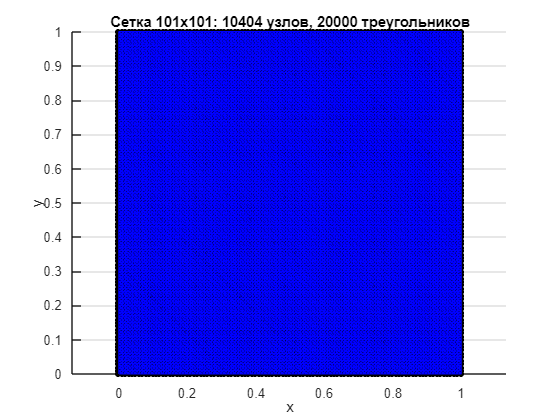

% Отрисовка сетки
coords = zeros(N^2,2);
for i = 1:N;
    for j = 1:N;
        coords(idx(j,i,N), :) = [(j-1)*h, (i-1)*h];
    end
end

tris = zeros(2*(N-1)^2, 3);
t = 0;
for i = 1:N-1
    for j = 1:N-1
        n00 = idx(j, i, N);
        n10 = idx(j+1,   i, N);
        n01 = idx(j, i+1,   N);
        n11 = idx(j+1,   i+1,   N);

        t = t + 1;
        tris(t,:) = [n00, n10, n01];   % T1'
        t = t + 1;
        tris(t,:) = [n10, n11, n01];   % T2'
    end
end

figure; hold on;
% Точки-узлы
plot(coords(:,1), coords(:,2), 'ko', 'MarkerSize', 4, 'MarkerFaceColor', 'k');
% Треугольники
triplot(tris, coords(:,1), coords(:,2), 'b-');
axis equal; grid on;
xlabel('x'); ylabel('y');
title(sprintf('Сетка %dx%d: %d узлов, %d треугольников', N, N, (N+1)^2, size(tris,1)));

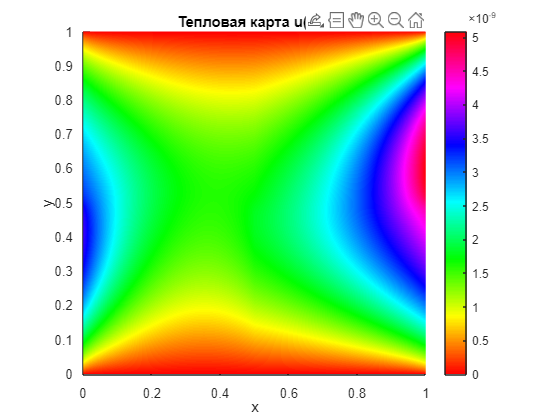

figure;
patch('Faces', tris, 'Vertices', coords, ...
      'FaceVertexCData', U, 'FaceColor', 'interp', 'EdgeColor', 'none');
colorbar; colormap hsv;
axis equal; axis tight;
xlabel('x'); ylabel('y');
title('Тепловая карта u(x,y)');

fig = figure;
